# APV RL Training

clear;
close all;
bdclose('all');
addpath("/home/momentumlab/Documents/git/AI-CPS-Ensemble/APV/model");

## Environment Setup

The parking lot environment used in this example is a subsection of the [Large Parking Lot](docid:driving_ref#mw_8ecb60fe-eb82-4f45-9629-a581750c6b69) scene. The parking lot is represented by the `ParkingLotEnvironment` object, which stores information on the ego vehicle, empty parking spots, and static obstacles (parked cars and boundaries). Each parking spot has a unique index number and an indicator light that is either green (free) or red (occupied). Parked vehicles are represented in black while other boundaries are outlined in green. 

Specify a sample time $T_s$ (seconds) for the controllers and a simulation time $T_f$ (seconds).

Ts = 0.1;
Ts_sample = 0.1;
Tf = 50;
freeSpotIndex = 32;
faceDirection = "south";    % parked car faces north or south

Create a reference path for the ego vehicle using the `createReferenceTrajectory` helper function included with this example. The reference path starts from the south-east corner of the parking lot and ends in the west as displayed with the dashed pink line.

xRef = createReferenceTrajectory(Ts,Tf,freeSpotIndex);

Create a `ParkingLotEnvironment` object with a free spot at index 32 and the specified reference path `xRef`.

map = ParkingLotEnvironment(freeSpotIndex,"Route",xRef);

Specify an initial pose $\left(X_0 ,Y_0 ,\theta_0 \right)$ for the ego vehicle. The units of $X_0$ and $Y_0$ are meters and $\theta_0$ is in radians.

egoInitialPose = [40 -55 pi/2];

Compute the target pose for the vehicle using the `createTargetPose` function. The target pose corresponds to the location in `freeSpotIdx`.

egoTargetPose = createTargetPose(map,freeSpotIndex,faceDirection);

## Sensor Modules

The parking algorithm uses geometric approximations of a camera and a lidar sensor to gather information from the parking lot environment.

### Camera

The field of view of a camera mounted on the ego vehicle is represented by the area shaded in green. The camera has a field of view $\varphi$ bounded by $\pm \pi /3$ radians and a maximum measurement depth $d_{\max }$ of 10 m. As the ego vehicle moves forward, the camera module senses the parking spots within the field of view and determines whether a spot is free or occupied. For simplicity, this action is implemented using geometrical relationships between the spot locations and the current vehicle pose. A parking spot is within the camera range if $d_i \le d_{\max }$ and $\varphi_{\min } \le \varphi_i \le \varphi_{\max }$, where $d_i$ is the distance to the parking spot and $\varphi_i$ is the angle to the parking spot.

### Lidar

The lidar sensor is modeled using radial line segments emerging from the geometric center of the vehicle. Distances to obstacles are measured along these line segments. The maximum measurable lidar distance along any line segment is 6 m. The reinforcement learning agent uses these readings to determine the proximity of the ego vehicle to other vehicles in the environment. The lidar sensor has 12 segmented lines which are passed into the observation vector of the RL agent as features.

## Auto Parking Valet Model

Load the auto parking valet parameters.

autoParkingValetParams3D
mdl = "APV_RL_training";

In this model:

- The vehicle dynamics are modeled in the Ego Vehicle Model subsystem. The dynamics is represented by a single-track bicycle kinematics model with two input signals: vehicle speed $v$ (m/s) and steering angle $\delta$ (radians).

- The adaptive MPC and RL agent blocks are found in the MPC Tracking Controller and RL Controller subsystems, respectively.

- Mode switching between the controllers is handled by the Vehicle Mode subsystem, which outputs Search and Park signals. Initially, the vehicle is in search mode and the adaptive MPC controller tracks the reference path. When a free spot is found, the Park signal activates the RL Agent to perform the parking maneuver.

Create the adaptive MPC controller object for reference trajectory tracking using the `createMPCForParking` script. For more information on adaptive MPC, see [Adaptive MPC](docid:mpc_ug#bujlmiz).

createMPCForParking3D;

## Reinforcement Learning Controller Design

To train the reinforcement learning agent, you must create an environment interface and an agent object.

### Create Environment

The environment for training is the region shaded in red in the following figure. Due to symmetry in the parking lot, training within this region is sufficient for the policy to adjust to other regions after coordinate transformations are applied to the observations. Constraining the training to this region also significantly reduces training duration when compared to training over the entire parking lot space.

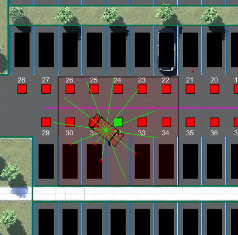

For this environment:

- The training region is a 13.625 m x 12.34 m space with the target spot at its horizontal center.

- The observations are the position errors $X_e$ and $Y_e$ of the ego vehicle with respect to the target pose, the sine and cosine of the true heading angle $\theta$, and the lidar sensor readings.

- The vehicle speed during parking is a constant 2 m/s.

- The action signals are discrete steering angles that range between +/- $\pi /4$ radians in steps of 0.2618 radians or 15 degrees.

- The vehicle is considered parked if the errors with respect to target pose are within specified tolerances of +/- 0.75 m (position) and +/-10 degrees (orientation).

- The episode terminates if the ego vehicle goes out of the bounds of the training region, collides with an obstacle, or parks successfully.

- The reward $r_t$ provided at time *t*, is:

                    
$$r_t =2e^{-\left(0\ldotp 05{X_e }^2 +0\ldotp 04{Y_e }^2 \right)} +0\ldotp 5e^{-40{\theta_e }^2 } -0\ldotp 05\delta^2 +100f_t -50g_t$$


Here, $X_e$, $Y_e$, and $\theta_e$ are the position and heading angle errors of the ego vehicle from the target pose, while $\delta$ is the steering angle. $f_t$ (0 or 1) indicates whether the vehicle has parked and $g_t$ (0 or 1) indicates if the vehicle has collided with an obstacle or left the training region at time $t$.

The coordinate transformations on vehicle pose $\left(X,Y,\theta \right)$ observations for different parking spot locations are as follows:

- Parking spots 1-14:   $\bar{X} =X,\bar{Y} =Y+20\ldotp 41,\;\bar{\theta} =\theta$

- Parking spots 15-28: $\bar{X} =41-X,\bar{Y} =-64\ldotp 485-Y,\;\bar{\theta} =\theta -\pi$

- Parking spots 29-37: $\textrm{no}\;\textrm{transformation}$

- Parking spots38-46: $\bar{X} =41-X,\bar{Y} =-84\ldotp 48-Y,\bar{\;\theta } =\theta -\pi$

Create the observation and action specifications for the environment.

nObs = 16;
nAct = 1;
observationInfo = rlNumericSpec([nObs 1]);
observationInfo.Name = "observations";
actionInfo = rlNumericSpec([nAct 1],"LowerLimit",-1,"UpperLimit",1);
actionInfo.Name = "actions";

% load simulink model
blk = mdl + "/Controller/RL Controller/RL Agent";
env = rlSimulinkEnv(mdl,blk,observationInfo,actionInfo);

Specify a reset function for training. The `autoParkingValetResetFcn` function resets the initial pose of the ego vehicle to random values at the start of each episode.

env.ResetFcn = @autoParkingValetResetFcn3D;

### Create Agent

The agent in this example is a twin-delayed deep deterministic policy gradient (TD3) agent. TD3 agents rely on actor and critic functions to learn the optimal policy. To learn more about TD3 agents, see [Twin-Delayed Deep Deterministic Policy Gradient Agents](docid:rl_ug#mw_3a8116dc-284e-4d85-a31c-0921ec03916e).

Set the random seed generator for reproducibility.

% rng(0)

% create critic
cnet = [
    featureInputLayer(nObs,"Normalization","none","Name","State")
    fullyConnectedLayer(128, "Name", "fc1")
    concatenationLayer(1,2,"Name","concat")
    reluLayer("Name","relu1")
    fullyConnectedLayer(128, "Name","fc3")
    reluLayer("Name","relu2")
    fullyConnectedLayer(1,"Name","CriticOutput")];

actionPath = [
    featureInputLayer(nAct,"Normalization","none","Name","Action")
    fullyConnectedLayer(128,"Name","fc2")];

criticNet = layerGraph(cnet);
criticNet = addLayers(criticNet, actionPath);
criticNet = connectLayers(criticNet,"fc2","concat/in2");

criticdlnet = dlnetwork(criticNet);
critic1 = rlQValueFunction(criticNet,observationInfo,actionInfo,...
    "ObservationInputNames","State","ActionInputNames","Action");
critic2 = rlQValueFunction(criticNet,observationInfo,actionInfo,...
    "ObservationInputNames","State","ActionInputNames","Action");

% create actor
anet = [featureInputLayer(nObs,"Normalization","none","Name","State")
    fullyConnectedLayer(128, "Name","actorFC1")
    reluLayer("Name","relu1")
    fullyConnectedLayer(128,"Name","actorFC2")
    reluLayer("Name","relu2")
    fullyConnectedLayer(nAct,"Name","Action")
    tanhLayer("Name","tanh1")];

actorNet = layerGraph(anet);
actordlnet = dlnetwork(actorNet);
actor = rlContinuousDeterministicActor(actordlnet,observationInfo,actionInfo,...
    "ObservationInputNames","State");

% agent options
agentOpts = rlTD3AgentOptions( ...
    "SampleTime",Ts, ...
    "DiscountFactor",0.99, ...
    "ExperienceBufferLength",1e6, ...
    "MiniBatchSize",128);

agentOpts.ExplorationModel.StandardDeviation = 0.1;
agentOpts.ExplorationModel.StandardDeviationDecayRate = 1e-4;
agentOpts.ExplorationModel.StandardDeviationMin = 0.01;

% Actor optimizer options
agentOpts.ActorOptimizerOptions.LearnRate = 1e-3;
agentOpts.ActorOptimizerOptions.GradientThreshold = 1;
agentOpts.ActorOptimizerOptions.L2RegularizationFactor = 1e-3;

% Critic optimizer options
agentOpts.CriticOptimizerOptions(1).LearnRate = 2e-3;
agentOpts.CriticOptimizerOptions(2).LearnRate = 2e-3;
agentOpts.CriticOptimizerOptions(1).GradientThreshold = 1;
agentOpts.CriticOptimizerOptions(2).GradientThreshold = 1;

% agent creation
agent = rlTD3Agent(actor,[critic1 critic2], agentOpts);

### Train Agent

To train the agent first specify the training options.

The agent is trained for a maximum of `10000` episodes with each episode lasting a maximum of `200` time steps. The training terminates when the maximum number of episodes is reached or the average reward over `200` episodes reaches the value of `120` or more. Specify the options for training using the [`rlTrainingOptions`](docid:rl_ref#mw_1f5122fe-cb3a-4c27-8c80-1ce46c013bf0) function.

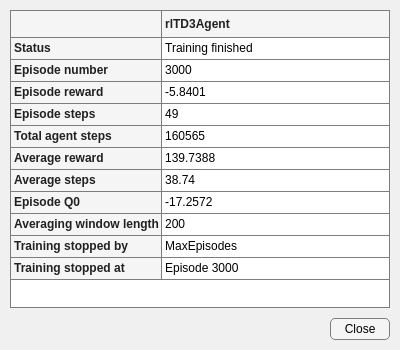

% semantics reward weights: [2,0.5,0.05] (default)
distWeight = 3;
orientWeight = 0.5;
stableWeight = 0.05;
rewardWeights = [distWeight, orientWeight, stableWeight];
maxsteps = 200;

trainOpts = rlTrainingOptions(...
    "MaxEpisodes",3000,...
    "MaxStepsPerEpisode",maxsteps,...
    "ScoreAveragingWindowLength",200,...
    "Plots","training-progress",...
    "StopTrainingCriteria","AverageReward",...
    "StopTrainingValue",300);

doTraining = true;
if doTraining
    trainingStats = train(agent,env,trainOpts);
else
    load("rlAutoParkingValetAgent.mat","agent");
end

## Save trained agent 

Save DRL agent with training configurations, agent configurations and training progress info

isSave = false;

if isSave
    dateOfTrain = date;
    agentName = ['APV-TD3-', dateOfTrain(1:end-5)];
    agentName = agentName+...
        "-"+string(rewardWeights(1))+...
        "-"+string(rewardWeights(2))+...
        "-"+string(rewardWeights(3));

    saveAgent = struct('agentName', agentName, ...
                 'agent', agent, ...
                 'rewardWeights', rewardWeights, ...
                 'agentOptions', agentOpts, ...
                 'criticNetwork', criticNet, ...
                 'actorNetwork', actorNet, ...
                 'trainOpts', trainOpts);

    path = "/home/momentumlab/Documents/git/AI-CPS-Ensemble/APV/DRL_training/trained_agent/";
    save(path+agentName+'.mat', "saveAgent");
    disp(agentName + ' saved')
end

APV-TD3-13-Jul-3-0.5-0.05 saved


## Simulation & Plotting

simOpts = rlSimulationOptions('MaxSteps',maxsteps,'StopOnError','on');

% get results
experiences = sim(env,agent,simOpts);

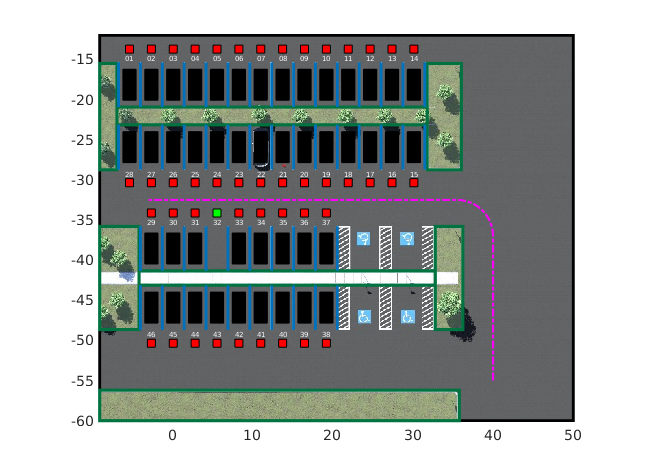

totalReward = sum(experiences.Reward);

% extract signals from simulation results
% time = experiences.SimulationInfo.tout;
% steps = size(time);
% steps = steps(1);
x_error = experiences.SimulationInfo.logsout.getElement('x_error').Values.Data;
steps = length(x_error);
time = 1:steps;

y_error =  experiences.SimulationInfo.logsout.getElement('y_error').Values.Data;
theta_error =  experiences.SimulationInfo.logsout.getElement('theta_error').Values.Data;
steer_angle =  experiences.SimulationInfo.logsout.getElement('steer_angle').Values.Data;
lidar_min_dist =  experiences.SimulationInfo.logsout.getElement('lidar_min_dist').Values.Data;
is_parked =  experiences.SimulationInfo.logsout.getElement('is_parked').Values.Data;
is_collision =  experiences.SimulationInfo.logsout.getElement('is_collision').Values.Data;

% theta_error = reshape(theta_error, [steps,1]);


figure(1);

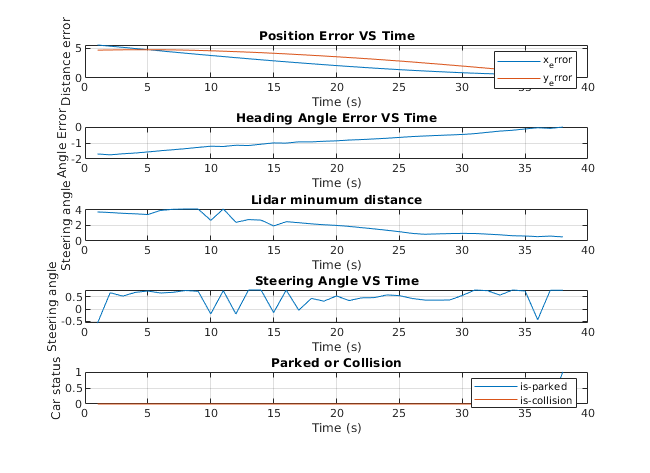

subplot(5,1,1)
plot(time,x_error, time,y_error)
title('Position Error VS Time')
legend('x_error', 'y_error')
xlabel('Time (s)') 
ylabel('Distance error') 
grid on

subplot(5,1,2)
plot(time,theta_error)
title('Heading Angle Error VS Time')
xlabel('Time (s)') 
ylabel('Angle Error') 
grid on

subplot(5,1,3)
plot(time,lidar_min_dist)
title('Lidar minumum distance')
xlabel('Time (s)') 
ylabel('Steering angle') 
grid on

subplot(5,1,4)
plot(time,steer_angle)
title('Steering Angle VS Time')
xlabel('Time (s)') 
ylabel('Steering angle') 
grid on
subplot(5,1,5)
plot(time,is_parked, time,is_collision)
title('Parked or Collision')
xlabel('Time (s)') 
legend('is-parked', 'is-collision')
ylabel('Car status') 
grid on

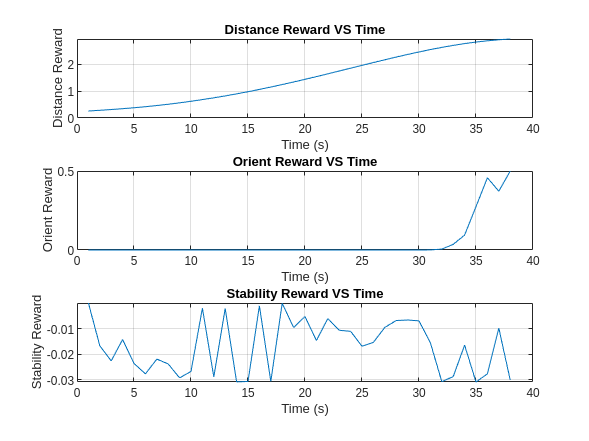

figure(2);
dist_reward =  experiences.SimulationInfo.logsout.getElement('dist_reward').Values.Data;
orient_reward =  experiences.SimulationInfo.logsout.getElement('orient_reward').Values.Data;
stable_reward =  experiences.SimulationInfo.logsout.getElement('stable_reward').Values.Data;

subplot(3,1,1)
plot(time,dist_reward)
title('Distance Reward VS Time')
xlabel('Time (s)') 
ylabel('Distance Reward') 
grid on

subplot(3,1,2)
plot(time,orient_reward)
title('Orient Reward VS Time')
xlabel('Time (s)') 
ylabel('Orient Reward') 
grid on

subplot(3,1,3)
plot(time,stable_reward)
title('Stability Reward VS Time')
xlabel('Time (s)') 
ylabel('Stability Reward') 
grid on

## Training progress info

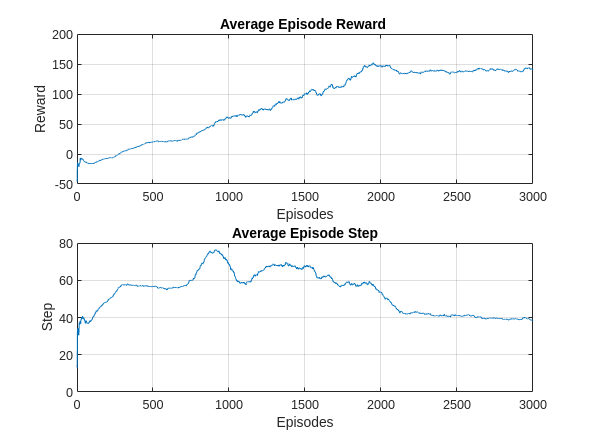

episodes = trainingStats.EpisodeIndex;
episode_reward = trainingStats.EpisodeReward;
episode_step = trainingStats.EpisodeSteps;
episode_avg_reward = trainingStats.AverageReward;
episode_avg_step = trainingStats.AverageSteps;

figure(3);
subplot(2,1,1)
plot(episodes,episode_avg_reward)
title('Average Episode Reward ')
xlabel('Episodes') 
ylabel('Reward') 
grid on

subplot(2,1,2)
plot(episodes,episode_avg_step)
title('Average Episode Step')
xlabel('Episodes') 
ylabel('Step') 
grid on